# `PROJECT: Cardiac Mitochondria`

`In this project, I plan to simulate five different experiments to explore the essential functions of mitochondria and how various conditions can affect its functionality. The project is based on the mitochondria base model from the mitochondria tutorial, and the model will be modified to represent the following five phenotypes:`

- `Health state`

- `Diabetic state`

- `Ischemia state`

- `High glucose, low fatty acids diet`

- `Low glucose, high fatty acids diet`

`This file, contains all the Matlab code used to recreate each experiment. This project would not be able without the aid of the cobraToolbox.`

`Autor: ``Rigoberto Rincón Ballesteros`

`07/27/2023`

#### `Initializing CobraToolbox`

initCobraToolbox(false); % initializing cobratoolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.41.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.
 > [mosek] Primal optimality condition in solveCobraLP satisfied.
 > [mosek] Dual optimality condition in solveCobraLP satisfied.

 > [matlab] Primal optimality condition in solveCobraLP satisfied.
   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:    

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    0 	    0 	    0 	    0 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    1 	    - 	    1 	    - 	    - 	    1
	matlab       	active        	    1 	    - 	    - 	    - 	    

changeCobraSolver('mosek','all') % select the solver of your preference


 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to mosek.

 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to mosek.

 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for EP problems has been set to mosek.
 > changeCobraSolver: Solver mosek not supported for problems of type MILP. Currently used: glpk 
 > changeCobraSol

ans = logical
   1


#### `Loading the Mitochondria model`

`Note: Make sure Mitochondria model is charge in your current path.`

load("CardicMitochondriaIT.mat"); % mitochondria model load as "model"

#### `Defining phenotypes`

`The following modifications were applied to the basic model in order to simulate the phenotype of five different conditions.`

`Health state`

modelnormal = model;
modelnormal = changeRxnBounds(modelnormal,'DM_atp(c)',7.5,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_acac(e)',-0.001,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_acac(e)',0,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_crvnc(e)',-0.156,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_crvnc(e)',-0.013,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_arachd(e)',-0.156,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_arachd(e)',-0.013,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_glc(e)',-0.875,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_glc(e)',-0.525,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_hb(e)',-0.001,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_hb(e)',0,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_hdca(e)',-1.250,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_hdca(e)',-0.1,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_lac-L(e)',-0.875,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_o2(e)',-39.1,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_o2(e)',-23.438,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdca(e)',-0.547,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdca(e)',-0.044,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcea(e)',-4.141,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcea(e)',-0.331,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcya(e)',-0.547,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcya(e)',-0.044,'u');
modelnormal = changeRxnBounds(modelnormal,'ATPtm',-32.6,'l');
modelnormal = changeRxnBounds(modelnormal,'ATPtm',32.6,'u');
modelnormal = changeRxnBounds(modelnormal,'CITRtm',-60,'l');
modelnormal = changeRxnBounds(modelnormal,'CITRtm',60,'u');
modelnormal = changeRxnBounds(modelnormal,'OCOAT1m',-16.9,'l');
modelnormal = changeRxnBounds(modelnormal,'OCOAT1m',16.9,'u');
modelnormal = changeRxnBounds(modelnormal,'SUCCt2m',-13.3,'l');
modelnormal = changeRxnBounds(modelnormal,'SUCCt2m',13.3,'u');

`Diabetic state`

modeldiab = model;
modeldiab = changeRxnBounds(modeldiab,'EX_acac(e)',-0.121,'l');
%modeldiab = changeRxnBounds(modeldiab,'EX_acac(e)',-0.020,'u');
modeldiab = changeRxnBounds(modeldiab,'EX_hb(e)',-0.106,'l');
modeldiab = changeRxnBounds(modeldiab,'EX_hb(e)',-0.016,'u');
modeldiab = changeRxnBounds(modeldiab,'EX_glc(e)',-0.644,'l');
modeldiab = changeRxnBounds(modeldiab,'EX_glc(e)',-0.386,'u');
modeldiab = changeRxnBounds(modeldiab,'C160CPT1',0.383,'l');
modeldiab = changeRxnBounds(modeldiab,'C160CPT1',0.4,'u');
modeldiab = changeRxnBounds(modeldiab,'C180CPT1',0.168,'l');
modeldiab = changeRxnBounds(modeldiab,'C180CPT1',0.183,'u');
modeldiab = changeRxnBounds(modeldiab,'C181CPT1',1.365,'l');
modeldiab = changeRxnBounds(modeldiab,'C181CPT1',1.380,'u');
modeldiab = changeRxnBounds(modeldiab,'C182CPT1',0.135,'l');
modeldiab = changeRxnBounds(modeldiab,'C182CPT1',0.151,'u');

`Ischemia state`

modelische = model;
modelische = changeRxnBounds(modelische,'EX_o2(e)',-9.766,'l');
modelische = changeRxnBounds(modelische,'EX_o2(e)',-5.859,'u');
modelische = changeRxnBounds(modelische,'EX_glc(e)',-2,'l');
modelische = changeRxnBounds(modelische,'EX_glc(e)',-0.7,'u');
modelische = changeRxnBounds(modelische,'EX_acac(e)',-1.359,'l');
%modelische = changeRxnBounds(modelische,'EX_acac(e)',-0.140,'u');
modelische = changeRxnBounds(modelische,'EX_hb(e)',-1.171,'l');
modelische = changeRxnBounds(modelische,'EX_hb(e)',-0.110,'u');

`High glucose, low fatty acids diet`

modellowfat = model;
modellowfat = changeRxnBounds(modellowfat,'EX_glc(e)',-1.5,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_glc(e)',-0.875,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_arachd(e)',-0.047,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_arachd(e)',-0.013,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_crvnc(e)',-0.047,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_crvnc(e)',-0.013,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_hdca(e)',-0.375,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_hdca(e)',-0.1,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdca(e)',-0.164,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdca(e)',-0.044,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcea(e)',-0.521,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcea(e)',-0.331,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcya(e)',-0.164,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcya(e)',-0.044,'u');

`Low glucose, high fatty acids diet`

modelhighfat = model;
modelhighfat = changeRxnBounds(modelhighfat,'EX_glc(e)',-0.263,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_glc(e)',-0.158,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_arachd(e)',-0.156,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_arachd(e)',-0.154,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_crvnc(e)',-0.036,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_crvnc(e)',-0.031,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hdca(e)',-0.467,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hdca(e)',-0.460,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdca(e)',-0.215,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdca(e)',-0.210,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcea(e)',-1.179,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcea(e)',-1.173,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcya(e)',-0.159,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcya(e)',-0.153,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_acac(e)',-0.324,'l');
%modelhighfat = changeRxnBounds(modelhighfat,'EX_acac(e)',-0.287,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hb(e)',-0.109,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hb(e)',-0.076,'u');

`All phenotypes`

`The following structures will be created to ease the manipulation of data extracted from each phenotype. ``Make sure labels corresponds to each model in phenotypes.`

phenotypes = {modelnormal;modeldiab;modelische;modellowfat;modelhighfat};
labels = {'Normal'; 'Diabetes'; 'Ischemic'; 'LowFat'; 'HighFat'};
if size(phenotypes) == size(labels) % phenotypes and labels must have same size
    disp('Phenotypes and labels arrays correct!')
else
    disp('Verify labels matches phenotypes');
    return
end

Phenotypes and labels arrays correct!


### `**Note: A struct array named "data" will be created to save all data that is going to be extracted from experiments.**`

#### `Mitochondria and Homeostasis`

`Experiment 1: `

`In this experiment, we aimed to determine the maximum and minimum fluxes of three different demand reactions to demonstrate the adaptability of cardiac mitochondria to various conditions.`

`First, I applied an FVA to determine the min and max fluxes and saved them in ``data array``.`

data = struct; % creating a struct array to saved FVA data

for i =1:length(labels) % defining fields for each phenotype
    data.(labels{i}) = {}; 
end

for i = 1:length(phenotypes)
    [minFlux,maxFlux] = fluxVariability((phenotypes{i}), 0); % aplying FVA 
    data.(labels{i}).minFluxes = minFlux;
    data.(labels{i}).maxFluxes = maxFlux;
end

`After calculating fluxes, I used min and max values to calculate the mean of three demand reactions: ATP, heme, and phospholipids reactions. Results will be added to a field named ``"means" `` in data array.`

atpDemandID = findRxnIDs(model, {'DM_atp(c)'}); % looking for IDs of relevant Rxns
hemeDemandID = findRxnIDs(model, {'DM_heme(m)'});
phoslipidDemandID = findRxnIDs(model, {'DM_phoslipid(m)'});

relevantRxnsIDs = {atpDemandID;hemeDemandID;phoslipidDemandID}; % grouping rxns IDs
relevantRxnsLabels = {'atpDemand','hemeDemand','phoslipidDemand'}; % labeling rxns

for i = 1:length(labels) % mean flux determination and saving
    for j = 1:length(relevantRxnsLabels)
        data.(labels{i}).means.(relevantRxnsLabels{j}) = ((data.(labels{i}).maxFluxes(relevantRxnsIDs{j})...
            + data.(labels{i}).minFluxes(relevantRxnsIDs{j}))/(2));
    end
end

`Finally, I created a table where I compiled information about these reactions and then I exported  table into a csv file. I used this file to personalized table in Ms Excel to show results.`

% creating a table for results
t1 = table(labels,{data.Normal.means.atpDemand;data.Diabetes.means.atpDemand;data.Ischemic.means.atpDemand;...
    data.LowFat.means.atpDemand;data.HighFat.means.atpDemand},{data.Normal.means.hemeDemand;data.Diabetes.means.hemeDemand...
    ;data.Ischemic.means.hemeDemand;data.LowFat.means.hemeDemand;data.HighFat.means.hemeDemand},{data.Normal.means.phoslipidDemand...
    ;data.Diabetes.means.phoslipidDemand;data.Ischemic.means.phoslipidDemand;data.LowFat.means.phoslipidDemand;...
    data.HighFat.means.phoslipidDemand},'VariableNames',{'Phenotypes','ATP demand','Heme Demand','Phospholipids demand'});
writetable(t1,'Experiment1_1.csv') % exporting table to a csv file

`Experiment 2:`

`As we all know, mitochondria play an essential role in cell survival, primarily due to their significant contribution to cellular energy production. In this experiment, we will assess the energetic performance of cardiac mitochondria. To achieve this, I will create a numeric factor (Efactor) representing the correlation between ATP production through the electron transport chain (ETC) and ATP demand: `

`Efactor = ATPdemand/ATPproduction`

`The underlying concept is that mitochondria need to maintain a sufficient energy supply in cardiac cells to ensure the proper functioning of the heart. This is effectively achieved through the ETC, where the majority of energy is produced in eukaryotic cells. I believe that this factor can provide valuable insights into how energetic performance may be affected under different conditions.`

`First, I searched ATP production reacion ID (ATPS4m) and used it to establish the range of ATP demand and ATP production in a 1x2 matrix format and saved it in ``data``.`

atpProdID = findRxnIDs(model, {'ATPS4m'}); % atp production rxn ID

% atp demand
for i = 1:length(labels)
    data.(labels{i}).atpDemandRange = [data.(labels{i}).minFluxes(atpDemandID),data.(labels{i}).maxFluxes(atpDemandID)];
end
% atp production on atp sinthasa rxn
for i = 1:length(labels)
    data.(labels{i}).atpProdRange = [data.(labels{i}).minFluxes(atpProdID),data.(labels{i}).maxFluxes(atpProdID)];
end

`After defining ATP demand and ATP productions ranges, I decided to create a graph to visualize the energetic performance of mitochondria thorugh specific range of ATP demand in each phenotype. To do so, first I created "plotTittles", "plots" and "Evalues" arrays in order to graph all phenotypes in a for loop structure. `

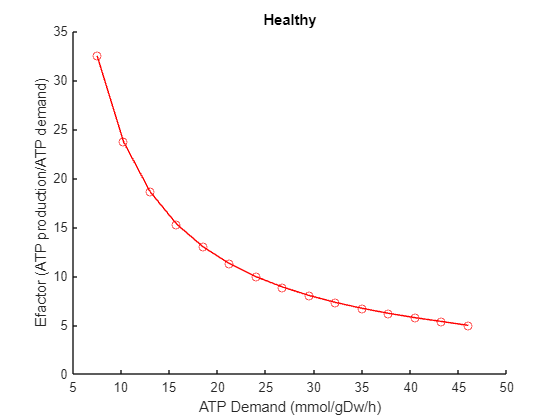

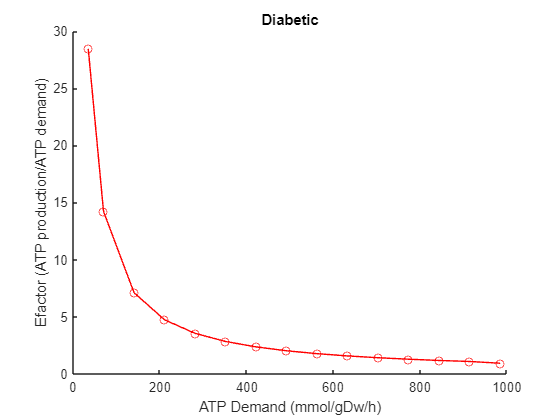

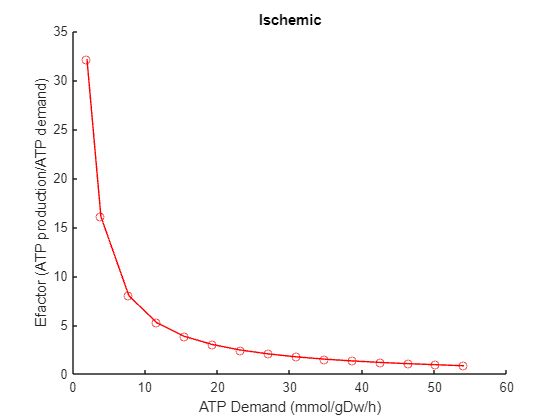

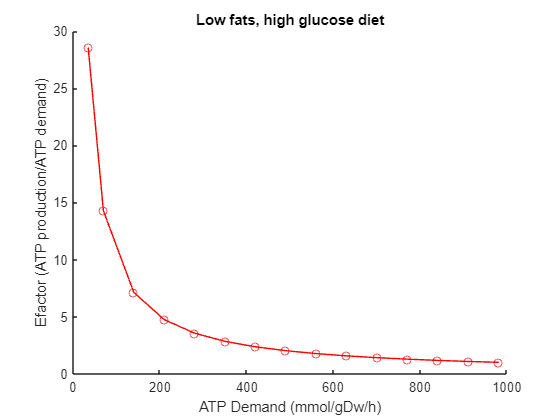

% creating labels to plot
plotTitles = {'Healthy';'Diabetic';'Ischemic';'Low fats, high glucose diet';'High fats, low glucose diet'};
plots = cell(length(phenotypes),1); 
EValues = cell(length(phenotypes),1);  % saving E values of each phenotype

for i = 1:length(phenotypes); % calculating E factor and plottin E vs atp Demand
    figure(i), hold on; % creating a figure
    x = linspace(data.(labels{i}).atpDemandRange(1),data.(labels{i}).atpDemandRange(1,2), 15); % plot 15 points of atpDemand
    if x(1) == 0 % when ATP demand min value is 0, it is changes for a new value between 0 and the second point
        diff = (x(3)-x(2));
        x(1) = ((diff/2) + 0);
    end
    phenotypes{i} = changeObjective(phenotypes{i},'ATPS4m'); % changing objective rxn
    atpProdRates = zeros(length(x),1); % atp production vector
    EFactor = zeros(length(x),1); % E factor empty array
    for j = 1:length(x)
        phenotypes{i} = changeRxnBounds(phenotypes{i},{'DM_atp(c)'},x(j), 'b'); % establish atpDemand points in model
        FBAatpProd = optimizeCbModel(phenotypes{i},'max'); % FBA
        atpProdRates(j) = FBAatpProd.f;
        EFactor(j) = (atpProdRates(j)/x(j)); % calculating E factor
    end
    EValues{i} = EFactor; % saving Efactor data
    % ploting
    plots{i} = atpProdRates;
    plot(x, EFactor,'o-','Color','red');
    xlabel('ATP Demand (mmol/gDw/h)');
    ylabel('Efactor (ATP production/ATP demand)');
    title([plotTitles{i}]);
end

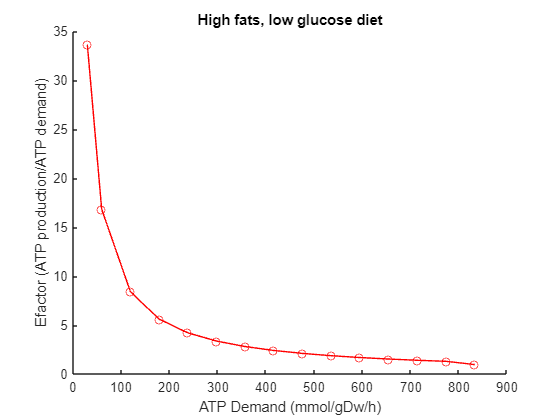

hold off;

`This graphs can be used to draw conclussion related to the behave of mitochondria under different conditions.`

#### `Redox detoxification changes`

`Experiment 3: `

`ROS detoxification plays a crucial role in cell survival. As a result, cell metabolism includes some antioxidant reactions that help maintain a ROS balance. Fortunately, the mitochondria model considers a tagged subsystem where we can find some of these reactions. In this experiment, my plan was to identified those reactions and analysis the impact of each reaction in ATP production thorugh ETC.`

`First, I identified ROS detox reactions in the model by looking for "ROS detoxification" subsystem in those reactions. After that, I added the ranges of each reaction to the ``data`` structure using FVA results. By using the ranges of each reaction, ``I calculated mean value for each reaction for each phenotype and added the sum of means of reactions to data in "means" field as "rosDetoxPAth". The mean of each reaction were also saved in data as rosDetoxFluxes, a vector with mean flux of each reaction of ROS detoxification system.`

rosDetoxSubsystem = 'ROS detoxification'; % looking for Ros detox rxns
rosDetoxRxnsID = find(ismember(model.subSystems,rosDetoxSubsystem)); 
rosDetoxRxns = model.rxns(rosDetoxRxnsID); % Ros detox rxns
rosDetoxRxnsMeans = zeros(length(rosDetoxRxns),1); % creating an empty vector to carry mean values of each rxn

for i = 1:numel(phenotypes) % array to save Ros detox rxns mean of each rxn in data
    data.(labels{i}).rosDetoxFluxes = zeros(length(rosDetoxRxns),1);
end

for i = 1:numel(phenotypes) % calculating mean of each ROS detox rxns
    for j = 1:numel(rosDetoxRxnsMeans)
        rosDetoxRxnsMeans(j) = ((data.(labels{i}).minFluxes(rosDetoxRxnsID(j)) + ... % calculating mean of each rxn
            data.(labels{i}).maxFluxes(rosDetoxRxnsID(j)))/2);
        data.(labels{i}).rosDetoxFluxes(j) = rosDetoxRxnsMeans(j); % adding the mean of each rxn to data struct
    end 
    data.(labels{i}).means.rosDetoxPath = sum(rosDetoxRxnsMeans); % sum of mean values and adding it to data
end

`After calculating the mean flux of every reaction involved in ROS detoxification and the sum of those reaction mean fluxes, I graphed a heatmap to provide a panoramic view of the most influential reaction in the total flux of the ROS detoxification mechanism. For this step, I organized results in a matrix format where rows represent phenotypes and columns represent reactions.`

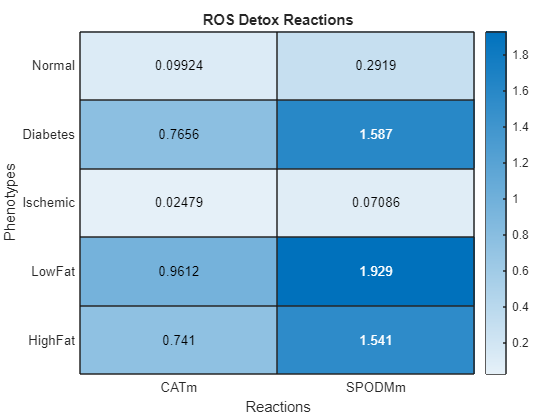

ROS_matrix = zeros(length(phenotypes), length(rosDetoxRxns)); % empty matrix
for i = 1:length(phenotypes)
    for j = 1:length(rosDetoxRxns)
        ROS_matrix(i,j) = data.(labels{i}).rosDetoxFluxes(j); % adding mean fluxes of each rxns to matrix
    end
end
rosMap = heatmap(ROS_matrix, 'XLabel','Reactions','YLabel','Phenotypes','Title','ROS Detox Reactions'); % heatmap
rosMap.XDisplayLabels = rosDetoxRxns;
rosMap.YDisplayLabels = labels;

`I decided to create two tables to present the results in a more organized format. The first table contained detailed information about the reactions involved in the ROS detoxification mechanism, including their chemical formulas, names, abbreviations, and the specific ROS species involved in each reaction. For this purpose I relied on the use of the MS Excel file wich contain all information about reactions and metabolites of mitochondria model in mitochondria tutorial.`

% first table
t = table(model.rxns(rosDetoxRxnsID),model.rxnNames(rosDetoxRxnsID), printRxnFormula(model,...
    model.rxns(rosDetoxRxnsID)),{'Hydrogen Peroxide';'SuperOxide'},{'h2o2';'o2s'});

CATm	2 h2o2(m) 	->	2 h2o(m) + o2(m) 
SPODMm	2 h(m) + 2 o2s(m) 	->	h2o2(m) + o2(m) 


t.Properties.VariableNames = {'Rxn abbv','Rxn name', 'Rxn formula', 'ROS name', 'ROS formula'};

`On the other hand, second table was created to group information related to the total flux of ROS detox system reactions (``sum of means of each reactions) ``and mean Efactor values in each phenotype. ``In order to do this, I used the Evalues saved on experiment 2. `

% second table
Emeans = cell(length(EValues),1);
for i = 1:numel(EValues)
    Emeans{i} = mean(EValues{i}); % calculating E mean of each phenotype
end
for i = 1:numel(labels)
    rosDetoxTotalMeans{i} = data.(labels{i}).means.rosDetoxPath; % grouping mean values of total flux of ROS detox rxns
end
rosDetoxTotalMeans = rosDetoxTotalMeans'; % transposing to create the table
t2 = table(plotTitles,rosDetoxTotalMeans,Emeans,'VariableNames',{'Phenotypes','Total Flux','Efactor'});

Bothe tables were then exported to a CSV file in order to personalize the first table and create a bar graph based on information of the second one.

writetable(t,'Experimert3.csv')  % export table in a csv file
writetable(t2,'Experiment3_1.csv');    

`Genetic knock-out analysis`

`Experiment 4: `

`Essential Genes are consider as those genes with vital relevance to cell,a simply alteration of the expression of those genes caused cell death. This experiment was based on the idea of used of the ``singleGeneDeletion ``cobratoolbox function to identify essential genes in each phenotype and then,`` make son comparison between phenotypes and see if there are some unique essential genes, whose I considered as essential genes specific of a phenotype compared with other.`

`First, I used the function to identify essential genes who commonly produces 0 ratio or a not consisten result in the ``grRatio`` output.`` Essential genes were then added to data  as "essentialGenesIDs" and "essentialGenes (gene names)".`

% looking for essential genes based on atp demand objective
for i = 1:length(phenotypes)
    phenotypes{i} = changeObjective(phenotypes{i},'DM_atp(c)');
    [grRatio,grRateKO,grRateWT,delRxns,hasEffesect] = singleGeneDeletion(phenotypes{i});
    essentialGenesIDs = find(grRatio == 0 | isnan(grRatio)); % genes, whose deletion cause inconsistency in model
    data.(labels{i}).essentialGenesIDs = essentialGenesIDs;
    data.(labels{i}).essentialGenes = phenotypes{i}.genes(essentialGenesIDs);
end

Single gene deletion analysis in progress ...
100%    [........................................]
Single gene deletion analysis in progress ...
100%    [........................................]
Single gene deletion analysis in progress ...
100%    [........................................]
Single gene deletion analysis in progress ...
100%    [........................................]
Single gene deletion analysis in progress ...
100%    [........................................]


`Once I identified the essential genes in each phenotype, I decided to perform two types of analyses.`` In the first type I compared the healthy phenotype with pathological ones (diabetes and Ischemia). On the other hand, second type, consisted in compare the healthy phenotype with the two different diets (low fatty acids/high glucose and high fatty acids/low glucose). ``Results were then added to data in a field named "uniqueEssentialGenes" in each model, except the normal (healthy) model.`

% grouping essential genes of each condition in a cell array of vectors
comparisonGroup = {data.Normal.essentialGenesIDs}; % genes IDs vector of helthy phenotype to compare with others

essentialGenesDiseasesGroup = {data.Diabetes.essentialGenesIDs;data.Ischemic.essentialGenesIDs};  % disease comparison
diseasesGroupLabels = {labels{2},labels{3}}; % creating labels for each group

essentialGenesDietGroup =  {data.Normal.essentialGenesIDs;data.LowFat.essentialGenesIDs;data.HighFat.essentialGenesIDs}; % diet comparison
dietGroupLabels = {labels{4},labels{5}};

% function to identify unique genes on disease comparison
for i = 1:numel(essentialGenesDiseasesGroup)
    for j = 1
        column = ismember(essentialGenesDiseasesGroup{i},comparisonGroup{j});
    end
    uniqueGenesIDs = find(~column); % unique genes refers to genes whose become essential in specific contidion
    data.(diseasesGroupLabels{i}).uniqueGenes = model.genes(essentialGenesDiseasesGroup{i}(uniqueGenesIDs));
end

% function to identify unique genes on disease comparison
for i = 1:numel(essentialGenesDiseasesGroup)
    for j = 1
        column = ismember(essentialGenesDietGroup{i},comparisonGroup{j});
    end
    uniqueGenesIDs = find(~column);
    data.(dietGroupLabels{i}).uniqueGenes = model.genes(essentialGenesDietGroup{i}(uniqueGenesIDs));
end

`After, I created a table and then exported it in a CSV file with the number of essential genes and unique genes identified in each phenotype to show results.`

 % creating arrays to group results
numberOfEssentialGenes = {numel(data.Normal.essentialGenes);numel(data.Diabetes.essentialGenes);...
    numel(data.Ischemic.essentialGenes);numel(data.LowFat.essentialGenes);numel(data.HighFat.essentialGenes)} ;% n° of Essential genes

numberOfUniqueEssentialGenes = {'-';numel(data.Diabetes.uniqueGenes);numel(data.Ischemic.uniqueGenes);...
    numel(data.LowFat.uniqueGenes);numel(data.HighFat.uniqueGenes)}; % n° of unique Essential Genes

t3 = table(plotTitles,numberOfEssentialGenes,numberOfUniqueEssentialGenes, 'VariableNames',{'Phenotypes',...
    'Essential Genes','Unique Essential Genes'}); % creating table
writetable(t3,'Experiment4.csv'); % exporting table in a CSV file

`I used unique essential genes analysis results and ``surfNet ``cobratoolbox function in order to explore reaction associate it with unique genes. `

`Note: For using the surfNet function some modifications needs to be implemented, I made changes to an altered model of cardiac mitochondria where basically I turn the GPR's into strings and replaced the | symbols for 'or'.`

% modifying original model
alteratedModel = model;
alteratedModel.rules = cellfun(@char, alteratedModel.rules, 'UniformOutput', false); % converting GPR's into strings
alteratedModel.rules = strrep(alteratedModel.rules, '|', 'or'); % replacing '|' symbol for 'or' in all GPR associations
surfNet(alteratedModel, '4705.1'); % surfNet use example


Gene #213  4705.1

Reactions involving the gene:
  #169  NADH2-u10m, Bd: 0 / 1000, NADH dehydrogenase, mitochondrial, grRules: (4715.1) and (4720.1) and (4719.1) and (4700.1) and (55967.1) and (4709.1) and (4710.1) and (4726.1) and (4718.

`Based on the latest results, I applied the SurfNet function to those phenotypes that possess unique essential genes and used results to create a table simultaneosly in MS Excel to show results.`

% diseases comparison
data.Diabetes.uniqueGenes

ans = 3×1 cell array
    {'1468.1' }
    {'6576.1' }
    {'23761.1'}


data.Ischemic.uniqueGenes % none unique essential genes


ans =

  0×1 empty cell array



surfNet(alteratedModel,data.Diabetes.uniqueGenes); % applying surfnet


Gene #22  1468.1

Reactions involving the gene:
  #38  AKGMALtm, Bd: -1000 / 1000, alpha-ketoglutarate/malate transporter, grRules: (8402.1) or (1468.1)
mal-L(c) + akg(m)   <=>   akg(c) + mal-L(m) 
  #164  MALtm, Bd: -1000 / 1000, malate transport, mitochondrial, grRules: (1468.1)


% diet comparison
data.LowFat.uniqueGenes % none unique essential genes


ans =

  0×1 empty cell array



data.HighFat.uniqueGenes

ans = 4×1 cell array
    {'1468.1'}
    {'435.1' }
    {'6576.1'}
    {'5009.1'}


surfNet(alteratedModel,data.HighFat.uniqueGenes);


Gene #22  1468.1

Reactions involving the gene:
  #38  AKGMALtm, Bd: -1000 / 1000, alpha-ketoglutarate/malate transporter, grRules: (8402.1) or (1468.1)
mal-L(c) + akg(m)   <=>   akg(c) + mal-L(m) 
  #164  MALtm, Bd: -1000 / 1000, malate transport, mitochondrial, grRules: (1468.1)


`Experiment 5: `

`Synthetic lethal genes are consider as a pair of genes whose abrubt dysfunction of both can have severe consecuences as death, altough dysfunction of genes individually will not cause those kind of consecuenses. This experiment focuses on searching for Synthetic lethal genes whose can cause a full decresed in ATP demand reaction (objective function) wich I considered as loss of the capability to harness energy, a fatal situation for cardiac cells.`

`In this case, I used the ``doubleGeneDeletion ``cobratoolbox function to find lethal synthetic interaction by the grRatioDble output. Once I obtained the indexes of those genes I reduces the candidates genes by comparing them with the essential genes of model itself. Finally I put those pairs in a ix2 matrix format (i value means thar rows depends on the number of interactions found) in wich it is meant that first pair of genes are in positions (1,1) and (1,2). After, lethal synthetic genes were added to ``data``.`

for i = 1:length(phenotypes)
    phenotypes{i} = changeObjective(phenotypes{i},'DM_atp(c)'); % defining objective
    [grRatioDble,grRateKODble,grRateWTDble] = doubleGeneDeletion(phenotypes{i}); 
    [rows, columns] = find(grRatioDble==0); % identifying where gene interactions caused a full decreased in objective
    isEssential = ismember(rows,data.(labels{i}).essentialGenesIDs) | ismember(columns,data.(labels{i}).essentialGenesIDs); % logical array
    rows(isEssential) = 0; % replacing essential genes indexes by "0"
    columns(isEssential) = 0;
    rowsLogic = find(rows); % looking for those not zero indexes
    columnsLogic = find(columns);
    gene1 = phenotypes{i}.genes(rows(rowsLogic)); % looking for gene names using genes IDs
    gene2 = phenotypes{i}.genes(columns(columnsLogic));
    data.(labels{i}).lethalSyntheticGenes = [gene1,gene2]; % grouping data in a matrix
end

Single deletion analysis to remove lethal genes
Single gene deletion analysis in progress ...
100%    [........................................]
323 non-lethal genes
Double gene deletion analysis
Total of 52003 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time
Single deletion analysis to remove lethal genes
Single gene deletion analysis in progress ...
100%    [........................................]
323 non-lethal genes
Double gene deletion analysis
Total of 52003 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time
Single deletion analysis to remove lethal genes
Single gene deletion analysis in progress ...
100%    [........................................]
323 non-lethal genes
Double gene deletion analysis
Total of 52003 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time
Single deletion analysis to remove lethal genes
Single gene deletion analysis in progress ...
100%    [......

`Lethal synthetic genes were then used to create a table and used after to create a bar graph in MS Excel to visualize the frecuency at wich these interaction were found in each phenotype.`

 % creating arrays to group results
numberOfLethalGenes = {length(data.Normal.lethalSyntheticGenes);length(data.Diabetes.lethalSyntheticGenes);...
    length(data.Ischemic.lethalSyntheticGenes);length(data.LowFat.lethalSyntheticGenes);...
    length(data.HighFat.lethalSyntheticGenes)}; % n° of Synthetic lethal Genes

numberOfLethalGenes = 5×1 cell array
    {[30]}
    {[30]}
    {[32]}
    {[42]}
    {[40]}


t4 = table(plotTitles,numberOfLethalGenes, 'VariableNames',{'Phenotypes','Lethal synthetic genes'}); % creating table
writetable(t4,'Experiment4_1.csv'); % exporting table in a CSV file

`To conclude, I want to highlight that this project is a clear example of utilizing the tools provided by the cobratoolbox in Matlab to explore genome-scale models. The results obtained from these experiments can lead to real-life experiments for validating the findings. Additionally, they may inspire other researchers to formulate new research questions or hypotheses in this or other types of models.`